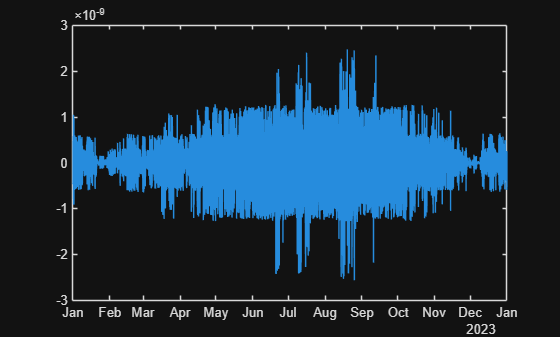

clear;
clc;
% Wymiary obiektu
a=1.84; % wysokość
b=42; % szerokość
c=10; % długość
d=4.77; % wysokość z dachem

% Dach
A_d=483.17; %Powierzchnia dachu
l1=5.752;
l2=5.759;
l3=5.782;
l4=5.795;
w_hd=5.722; %Wymiar charakterystyczny dachu
Re_d=918.117; %Liczba Reynolds dachu
A_rad=b*l4; %Powierzchnia radiacji

%Warstwa szkła
delta_1=0.003;
lambda_1=0.8;
tau_1=0.82;

%Warstwa powietrza
delta_2=0.01;
lambda_2=0.0244;
tau_2=1;

%Wartswa foli
delta_3=0.006;
lambda_3=0.19;
tau_3=0.62;

%Ściana
A_s=154.56; %powierzchnia ściamy bocznej
A_p=132.2;  %powierzchnia ściany przedniej
w_hp=3.305; %Wymiary charakterystyczny ściany przedniej
Re_p=527.534;
w_hs=1.84; %Wymiary charakterystyczny ściany bocznej

A_c=A_s + A_p + A_d;  %suma

%Grunt
A_g=419.92; %powierzchnia gruntu
delta_g=2;
lambda_g=1.49;
w_hg=(b^2+c^2)^0.5;

%Paramtery wewnętrzne
v_in=0.00001472;
Pr_in=0.704;
lambda_in=0.0253;
alpha_s = 0.52; %solar radiation absorbance

%Parametry zewnętrzne
v_out=0.00001253;
lambda_out=0.02302;
Re_s=293.695;

%Wartości stałe
g=9.8815;
phi=0.5154; %radiany
c_w=0.8*(1+1*(1+1/((Pr_in^0.5)))^2)^(-0.25);
R_warstw=(delta_1/lambda_1)+(delta_2/lambda_2)+(delta_3/lambda_3);
rho_pin=1.23; %gęstość powietrza w środku szklarni
ni=0.7; %sprawność procsu radiacji

V=b*(a*c+(c*(d-a))/2); %objętość szklarni
m_pow=rho_pin*V; %masa powietrza w szklarni


%nastawy
Qcover=500; %stosowanie dodatkowego zacienienia przy danej radiacji
Tcover=-20;   %stosowanie dodatkowego zacienienia przy danej temperaturze zewnętrznej
tau_4 = 0.47; %dodatkowe cieniowanie szklarni w ciągu gorących dni
R_l=1.5; %oporność wentylacj
U_l=1/R_l;
Tset_min = 12;
Tset_max = 15;
Q_on   = 300;
Q_full = 600;
tau_base = tau_1 * tau_2 * tau_3;



%% --- STRUKTURA PARAMETRÓW DLA FUNKCJI ---
params = struct( ...
    'A_s',A_s,'A_p',A_p,'A_d',A_d,'A_g',A_g, ...
    'b',b,'l4',l4,'R_warstw',R_warstw, ...
    'lambda_in',lambda_in,'lambda_out',lambda_out, ...
    'w_hs',w_hs,'w_hp',w_hp,'w_hd',w_hd,'w_hg',w_hg, ...
    'g',g,'phi',phi,'Pr_in',Pr_in,'v_in',v_in, ...
    'delta_g',delta_g,'lambda_g',lambda_g, ...
    'ni',ni,'tau_1',tau_1,'tau_2',tau_2,'tau_3',tau_3, ...
    'R_l',R_l,'rho_pin',rho_pin, ...
    'V', V, 'c_w', c_w, 'm_pow', m_pow, 'alpha_s', alpha_s, 'Qcover', Qcover, 'tau_4',tau_4, ...
    'Tcover', Tcover, 'A_rad', A_rad, 'Tset_min', Tset_min, 'Tset_max', Tset_max, ...
    'Q_on', Q_on, 'Q_full', Q_full, 'tau_base', tau_base);


T=readtable('series2023.csv','VariableNamingRule', 'preserve');
T.time = datetime(T.time, 'InputFormat','yyyyMMdd:HHmm', 'TimeZone','UTC');
T.temp_zew=T{:,4};
T.I_c=T{:,2};
T.w_w=T{:,5};
T.H_sun=T{:,3};  %wysokość słońca
params.w_w=T.w_w;


validRows = ~isnat(T.time) & ...
            ~isnan(T.temp_zew) & ...
            ~isnan(T.I_c)      & ...
            ~isnan(T.w_w);

lastGood = find(validRows, 1, 'last');   % indeks ostatniego dobrego wiersza

T = T(1:lastGood, :);    % przycięcie tabeli

T_pow=readtable('powietrze.xlsx','VariableNamingRule', 'preserve');
t=T_pow{:,1};
v_kin=T_pow{:,2};
cp=T_pow{:,3};
Pr=T_pow{:,4};

params.t_air   = t;
params.v_kin_T = v_kin;
params.cp_T    = cp;
params.Pr_T    = Pr;

T.v_kin = interp1(t,v_kin,T.temp_zew,'linear');
T.cp_out = interp1(t,cp,T.temp_zew,"linear");
cp_in = interp1(t,cp,14,"linear");
T.Pr_out = interp1(t,Pr,T.temp_zew,"linear");

Tg=readtable('grunt.csv','VariableNamingRule', 'preserve');
Tg.time = datetime(Tg.time, 'InputFormat','yyyy-MM-dd''T''HH:mm', 'TimeZone','UTC');
Tg.t_gr=Tg{:,2};
T.t_gr = interp1(Tg.time, Tg.t_gr, T.time, 'previous');

n  = height(T);


%--------------------------POJEMNOŚĆ CIEPLNA--------
n_don = 6500;                           %ilość doniczek
v_don = 0.003;                          %objętość doniczki [m3]
cp_w  = 4190.71;                        %ciepło właściwe wody
rho_w = 999.31;                         %gęstość wody
cp_torf = 1920;                         %ciepło właściwe torfu - reszta to powietrze
rho_torf = 1500;                        %gęstość torfu
cp_pow = 1015;                          %ciepło właściwe powietrza przy 70% wilgotności

%kwiaty
m_start = 0.02;
m_stop = 0.15;
cykl = 60 * 24;                %60dni - w godzinach
cp_kwiat = 3900;


k = (0:n-1)';

% liniowy wzrost z resetem co 'cykl' godzin
phase    = mod(k, cykl) / (cykl-1);                    % 0 → 1
m_kwiat  = m_start + (m_stop - m_start) .* phase;      % masa w czasie

%pojemnosci cieplne poszczegolnych elementow
c_torf = v_don * cp_torf * rho_torf * 0.1;
c_wody =  v_don * cp_w * rho_w * 0.4;
c_kwiat = cp_kwiat .* m_kwiat;
c_pow = m_pow * cp_pow;

c_eff = n_don * (c_torf + c_wody + c_kwiat) + c_pow; 

params.c_eff = c_eff;
params.cp_pow = cp_pow;


%------------------WENTYLACJA------------
function [U, Q_vent, U_v, G_vent] = vent_model(T_ctrl, T_Q, Tamb, w_w, p)

Tset_max=p.Tset_max; Tset_min=p.Tset_min; cp_pow=p.cp_pow; A_g=p.A_g; g=p.g; rho_pin=p.rho_pin; H_sun=p.H_sun;

%współczynniki
A_1 = 0.664;        % wspolczynnik przepływu
cw = 0.09;          % wspolczynnik wiatru
H = 0.6;            % wysokość czynna otworu
% wywietrzniki
L_v = 10;           % długość całkowita wywietrzników
l_v = 0.5;          % szereokość jednego wywietrznika
Amax = L_v* l_v;    % max powierzchnia otworów
% parametry sterowania
Tset_v = Tset_max;  % poniżej okna zamknięte
Pband = 30;         % szerokość pasma proporcjonalnego
w_min = 2.5;        % minimalny wiatr do wietrzenia
H_lim =0;           % wietrzymy tylko w nocy


% sterowanie otwarciem okien

    dT_vent = T_ctrl - Tset_v;
    dT_cool = T_ctrl - Tamb;
    sun_ok = (H_sun<=H_lim);
    temp_ok = (Tamb >= Tset_min-5) && (Tamb <= Tset_max + 10); 
  
    if ((dT_vent <= 0) || (dT_cool<=-2) || (w_w < w_min)) || ~temp_ok || ~sun_ok
        U = 0;
    elseif dT_vent >= Pband
        U = 1;
    else
        U = dT_vent / Pband;
    end

S = U * Amax;                   % efektywna powierzchnia otwarcia
Tsr = (T_Q + Tamb)/2 +273.15;  % średnia temperatura

% strumień wentylacji
term_buoy = g * H .* abs(T_Q - Tamb) ./ (2 * Tsr);  % składowa unoszeniowa
term_wind = cw .* w_w.^2;                            % składowa od wiatru
radicand = term_buoy + term_wind;                   

G_vent = (S/2) .* A_1 .* sqrt(radicand);   % [m3/s]

Q_vent = rho_pin * cp_pow .* G_vent .* (T_Q - Tamb);
U_v = (rho_pin * cp_pow .* G_vent) / A_g;

end


    



%% Symulacja roczna pełnym modelem fizycznym

dt = 3600;                 % krok czasowy [s]


Tin_sim    = zeros(n,1);
Tin_sim(1) = T.temp_zew(1);    % warunek startowy, możesz zmienić np. na 15
U_s_arr   = zeros(n,1);
U_p_arr   = zeros(n,1);
U_d_arr   = zeros(n,1);
Q_s_arr   = zeros(n,1);
Q_p_arr   = zeros(n,1);
Q_d_arr   = zeros(n,1);
Q_g_arr   = zeros(n,1);
Q_rad_arr = zeros(n,1);
Q_l_arr   = zeros(n,1);
Q_net_arr = zeros(n,1);
Q_vent_arr = zeros(n,1);
U_arr = zeros(n,1);
U_v_arr = zeros(n,1);
err_v_arr = zeros(n,1);
tau_eff_arr = zeros(n,1);
Q_h_arr = zeros(n,1);
Q_c_arr = zeros(n,1);
params.active_control = false;


% ------- szklarnia pasywna
for k = 1:n-1

    % aktualizacja parametrów zależnych od chwili czasu
    params.w_w   = T.w_w(k);    % prędkość wiatru w tej godzinie
    params.tgr_med = T.t_gr(k);   % temperatura gruntu w tej godzinie
    params.c_eff   = c_eff(k);

    Tamb_k = T.temp_zew(k);       % [°C]
    Ic_k   = T.I_c(k);            % [W/m2]
    Tin_k  = Tin_sim(k);          % temperatura wewnętrzna z poprzedniej godziny
    params.H_sun = T.H_sun(k);    % wysokość słońca

 [Tin_sim(k+1), U_s_arr(k), U_p_arr(k), U_d_arr(k), Q_s_arr(k), Q_p_arr(k), Q_d_arr(k), Q_g_arr(k), ...
 Q_rad_arr(k), Q_l_arr(k), Q_net_arr(k), Q_vent_arr(k), U_arr(k), U_v_arr(k), err_v_arr(k), ...
 tau_eff_arr(k), Q_h_arr(k), Q_c_arr(k)] = ...
    step_Tk_physics(Tamb_k, Ic_k, Tin_k, dt, params);

end

% zapisz wynik do tabeli
T.Tin = Tin_sim;
T.U_s   = U_s_arr;
T.U_p   = U_p_arr;
T.U_d   = U_d_arr;
T.Q_s   = Q_s_arr;
T.Q_p   = Q_p_arr;
T.Q_d   = Q_d_arr;
T.Q_g   = Q_g_arr;
T.Q_rad = Q_rad_arr;
T.Q_l   = Q_l_arr;
T.Q_net = Q_net_arr;
T.Q_vent = Q_vent_arr;
T.U = U_arr;
T.U_v = U_v_arr;
T.err_v = err_v_arr;
T.tau_eff = tau_eff_arr;
T.Q_h_sim = Q_h_arr;
T.Q_c_sim = Q_c_arr;




%% ----------- szklarnia z kontrolą klimatu (minimalna moc dostarczona do szklarni)

Tin_active    = zeros(n,1);
Tin_active(1) = T.temp_zew(1);
U_s_act   = zeros(n,1);
U_p_act   = zeros(n,1);
U_d_act   = zeros(n,1);
Q_s_act   = zeros(n,1);
Q_p_act   = zeros(n,1);
Q_d_act   = zeros(n,1);
Q_g_act   = zeros(n,1);
Q_rad_act = zeros(n,1);
Q_l_act   = zeros(n,1);
Q_net_act = zeros(n,1);
Q_vent_act = zeros(n,1);
U_act = zeros(n,1);
U_v_act = zeros(n,1);
err_v_act = zeros(n,1);
tau_eff_act = zeros(n,1);
Q_h_act = zeros(n,1);
Q_c_act = zeros(n,1);
G_vent_act = zeros(n,1);
params.active_control = true;

for k = 1:n-1
    params.w_w = T.w_w(k); 
    params.tgr_med = T.t_gr(k);
    params.c_eff = c_eff(k);
    params.H_sun = T.H_sun(k);
    params.Tpassive = T.Tin(k);         % T.Tin = wynik pasywnej szklarni

    Tamb_k = T.temp_zew(k);       % [°C]
    Ic_k   = T.I_c(k);            % [W/m2]
    Tin_k  = Tin_active(k);          % temperatura wewnętrzna z poprzedniej godziny
    params.H_sun = T.H_sun(k);    % wysokość słońca


[Tin_active(k+1), U_s_act(k), U_p_act(k), U_d_act(k), Q_s_act(k), Q_p_act(k), Q_d_act(k), Q_g_act(k), ...
 Q_rad_act(k), Q_l_act(k), Q_net_act(k), Q_vent_act(k), U_act(k), U_v_act(k), err_v_act(k), ...
 tau_eff_act(k), Q_h_act(k), Q_c_act(k), G_vent_act(k)] = ...
    step_Tk_physics(Tamb_k, Ic_k, Tin_k, dt, params);
end

% Zapisujemy wyniki aktywne
T.Tin_active = Tin_active;
T.U_s_act   = U_s_act;
T.U_p_act   = U_p_act;
T.U_d_act   = U_d_act;
T.Q_s_act  = Q_s_act;
T.Q_p_act   = Q_p_act;
T.Q_d_act   = Q_d_act;
T.Q_g_act   = Q_g_act;
T.Q_rad_act = Q_rad_act;
T.Q_l_act   = Q_l_act;
T.Q_net_act = Q_net_act;
T.Q_vent_act = Q_vent_act;
T.U_act = U_act;
T.U_v_act = U_v_act;
T.err_v_act = err_v_act;
T.tau_eff_act = tau_eff_act;
T.Q_h_act = Q_h_act;
T.Q_c_act = Q_c_act;
T.G_vent_act = G_vent_act;



%% ----------- szklarnia z kontrolą klimatu (maksymalna moc dostarczona do szklarni)

% --- maksymalne zapotrzebowanie grzewcze: Tset_min = Tset_max = 15°C
params_heating = params;
params_heating.Tset_min = 15;
params_heating.Tset_max = 15;   % brak martwej strefy, grzejemy / chłodzimy do 15°C

Tin_h    = zeros(n,1);
Tin_h(1) = T.temp_zew(1);
Q_h_15   = zeros(n,1);

for k = 1:n-1
    params_heating.w_w      = T.w_w(k); 
    params_heating.tgr_med  = T.t_gr(k);
    params_heating.c_eff    = c_eff(k);
    params_heating.H_sun    = T.H_sun(k);
    params_heating.Tpassive = T.Tin(k);   % dalej korzystasz z pasywnej

    Tamb_k = T.temp_zew(k);
    Ic_k   = T.I_c(k);

    [Tin_h(k+1), ~,~,~,~,~,~,~,~,~,~,~,~,~,~,~, ...
                  Q_h_15(k), ~, ~] = ...
        step_Tk_physics(Tamb_k, Ic_k, Tin_h(k), dt, params_heating);
end

T.Q_h_15 = Q_h_15;              % seria godzinowa
Q_h_15_max = max(Q_h_15);       % maksymalna moc grzewcza [W]
E_h_15 = sum(Q_h_15)*dt;        % energia w [J], jak potrzebujesz


% --- maksymalne zapotrzebowanie chłodnicze: Tset_min = Tset_max = 12°C
params_cooling = params;
params_cooling.Tset_min = 12;
params_cooling.Tset_max = 12;   % brak martwej strefy, regulacja na 12°C

Tin_c    = zeros(n,1);
Tin_c(1) = T.temp_zew(1);
Q_c_12   = zeros(n,1);

for k = 1:n-1
    params_cooling.w_w      = T.w_w(k); 
    params_cooling.tgr_med  = T.t_gr(k);
    params_cooling.c_eff    = c_eff(k);
    params_cooling.H_sun    = T.H_sun(k);
    params_cooling.Tpassive = T.Tin(k);

    Tamb_k = T.temp_zew(k);
    Ic_k   = T.I_c(k);

    [Tin_c(k+1), ~,~,~,~,~,~,~,~,~,~,~,~,~,~,~, ...
                  ~, Q_c_12(k), ~] = ...
        step_Tk_physics(Tamb_k, Ic_k, Tin_c(k), dt, params_cooling);
end

T.Q_c_12 = Q_c_12;            % seria godzinowa
Q_c_12_max = max(Q_c_12);     % maksymalna moc chłodnicza [W]
E_c_12 = sum(Q_c_12)*dt;      % energia chłodnicza






%% ---------------------------------------------------------------
function [Tk, U_s, U_p, U_d, Q_s, Q_p, Q_d, Q_g, Q_rad, Q_l, Q_net, Q_vent, U, U_v, err_v, tau_eff, Q_h, Q_c, G_vent] ...
= step_Tk_physics(Tamb, Ic, Tin, dt, p)


    % --- Stałe fizyczne z parametru p ---
    A_s=p.A_s; A_p=p.A_p; A_d=p.A_d; A_g=p.A_g;
    b=p.b; l4=p.l4;
    R_warstw=p.R_warstw;
    lambda_in=p.lambda_in; lambda_out=p.lambda_out;
    w_hs=p.w_hs; w_hp=p.w_hp; w_hd=p.w_hd; w_hg=p.w_hg;
    g=p.g; phi=p.phi; Pr_in=p.Pr_in; v_in=p.v_in;
    delta_g=p.delta_g; lambda_g=p.lambda_g;
    ni=p.ni; tau_1=p.tau_1; tau_2=p.tau_2; tau_3=p.tau_3;
    R_l=p.R_l; rho_pin=p.rho_pin; V=p.V; c_w=p.c_w; t_inter=p.t_air; 
    v_kin_inter=p.v_kin_T; cp_inter=p.cp_T;
    Pr_inter=p.Pr_T; w_w=p.w_w;
    m_pow=p.m_pow; t_gr=p.tgr_med;
    Qcover=p.Qcover; alpha_s=p.alpha_s; tau_4=p.tau_4; c_eff=p.c_eff; Tcover=p.Tcover; cp_pow=p.cp_pow; A_rad=p.A_rad;
    Tset_min=p.Tset_min; Tset_max=p.Tset_max; H_sun=p.H_sun;
    Q_on=p.Q_on; Q_full=p.Q_full; tau_base=p.tau_base;


    if isfield(p,'Tpassive')
        Tpassive = p.Tpassive;
    else
        Tpassive = Tin;   
    end
    
substeps = 60;          
dt_sub = dt / substeps; 
    
Tloc = Tin;

E_h=0;
E_c=0;


    for j = 1:substeps

Tloc_old = Tloc;

v_kin = interp1(t_inter,v_kin_inter,Tamb,'linear', 'extrap');
Pr_out = interp1(t_inter,Pr_inter,Tamb,"linear", 'extrap');
cp_in = interp1(t_inter,cp_inter,Tloc,"linear", 'extrap');

Re_sout=w_w*w_hs ./ v_kin;
Re_pout=w_w*w_hp ./ v_kin;
Re_dout=w_w*w_hd ./ v_kin;

Nu_sout=0.644*((Re_sout).^0.5).*(Pr_out.^0.33);
Nu_pout=0.644*((Re_pout).^0.5).*(Pr_out.^0.33);
Nu_dout=0.644*((Re_dout).^0.5).*(Pr_out.^0.33);


tol   = 1e-3;     
alpha = 0.8;     
maxit = 300;

t_s1 = 10;
t_p1 = 10;
t_d1 = 10;
t_g1 = t_gr;

for it = 1:maxit

    
beta_s=1./((Tloc+t_s1)./2+273.15);
beta_p=1./((Tloc+t_p1)./2+273.15);
beta_d=1./((Tloc+t_d1)./2+273.15);
beta_g=1./((Tloc+t_g1)./2+273.15);

Gr_sin = (g * beta_s .* abs(Tloc - t_s1) * w_hs^3) / (v_in^2);
Gr_pin = (g * beta_p .* abs(Tloc - t_p1) * w_hp^3) / (v_in^2);
Gr_din = (g * beta_d .* abs(Tloc - t_d1) * w_hd^3) / (v_in^2);
Gr_gin = (g * beta_g .* abs(Tloc - t_g1) * w_hg^3) / (v_in^2);

Nu_sin = c_w*(Gr_sin.*Pr_in).^0.25;
Nu_pin = c_w*(Gr_pin.*Pr_in).^0.25;
Nu_din = 0.56*(Gr_din*Pr_in*cos(phi)).^0.25;
Nu_gin = 0.135*(Gr_gin.*Pr_in).^0.25;

h_sin = Nu_sin * lambda_in / w_hs;
h_pin = Nu_pin * lambda_in / w_hp;
h_din = 1.3 * Nu_din * lambda_in / w_hd;
h_gin = Nu_gin * lambda_in / w_hg;

h_sout = Nu_sout * lambda_out / w_hs;
h_pout = Nu_pout * lambda_out / w_hp;
h_dout = Nu_dout * lambda_out / w_hd;

U_s = 1 ./ ((1./h_sin) + R_warstw + (1./h_sout));
U_p = 1 ./ ((1./h_pin) + R_warstw + (1./h_pout));
U_d = 1 ./ ((1./h_din) + R_warstw + (1./h_dout));

q_s = U_s .* (Tloc - Tamb);
q_p = U_p .* (Tloc - Tamb);
q_d = U_d .* (Tloc - Tamb);
q_g = (Tloc - t_gr) ./ (1 ./ (0.7 .* h_gin) + (delta_g / lambda_g));

dTs = q_s / h_sin;
dTp = q_p / h_pin;
dTd = q_d / h_din;

t_s1new = Tloc - dTs;
t_p1new = Tloc - dTp;
t_d1new = Tloc - dTd;

    err = max([ max(abs(t_s1new - t_s1)), ...
                max(abs(t_p1new - t_p1)), ...
                max(abs(t_d1new - t_d1)) ]);

t_s1 = alpha*t_s1new + (1-alpha)*t_s1;
t_p1 = alpha*t_p1new + (1-alpha)*t_p1;
t_d1 = alpha*t_d1new + (1-alpha)*t_d1;

 if err < tol, break; end
end

Q_s = q_s .* A_s;
Q_p = q_p .* A_p;
Q_d = q_d .* A_d;
Q_g = q_g .* A_g;


if ((Tamb <= Tcover) || (Ic <= Q_on) )|| (Tloc < Tset_min)
    f = 0;                         % brak zacienienia
elseif Ic >= Q_full 
    f = 1;                         % pełne zacienienie
else
    f = (Ic - Q_on) / (Q_full - Q_on);  
end
tau_eff  = tau_base * (1 - f*(1 - tau_4));


Q_rad= ni .* Ic * A_rad * tau_eff*alpha_s;

A_c=A_s + A_p + A_d;

Q_l = (A_c / R_l) * (Tloc - Tamb);



%-----WENTYLACJA ----------------------------------


Tref = (Tset_min + Tset_max)/2;


if p.active_control
    % w trybie z regulacją: wywietrzniki sterujesz temperaturą pasywną
    T_ctrl_vent = Tpassive;
else
    % w trybie pasywnym
    T_ctrl_vent = Tloc;
end


[U, Q_vent, U_v, G_vent] = vent_model(T_ctrl_vent, Tref, Tamb, w_w, p);


%---------pasywny bilans
Q_net_passive = Q_rad - (Q_s+Q_p+Q_d+Q_g+Q_l+Q_vent);
Q_h_sub = 0;
Q_c_sub = 0;
T_free = Tloc + (Q_net_passive * dt_sub) / c_eff;



% --- 3. LOGIKA TERMOSTATU (REGULATORA) ---
        
        Q_h = 0; % Chwilowa moc grzewcza [W]
        Q_c = 0; % Chwilowa moc chłodnicza [W]
        Q_h_sub = 0;
        Q_c_sub = 0;

  if p.active_control == true

        if T_free < Tset_min
            Tctrl   = Tset_min;
            % Jest za zimno -> GRZEJEMY
            Q_h_sub = c_eff * (Tset_min - T_free) / dt_sub;

     
        elseif T_free > Tset_max
            Tctrl   = Tset_max;
            % Jest za gorąco -> CHŁODZIMY
            Q_c_sub = c_eff * (T_free -Tset_max) / dt_sub;


        else
            % Temperatura w normie 
            Tctrl = T_free;
        end
  else 

      % tryb pasywny
      Tctrl = T_free;
  
  end
Tloc=Tctrl;


% akumulacja energii
E_h = E_h + Q_h_sub*dt_sub;
E_c = E_c + Q_c_sub*dt_sub;


Q_net = Q_net_passive + Q_h_sub - Q_c_sub;
Q_loss = Q_s + Q_p + Q_d + Q_g + Q_l + Q_vent + Q_c_sub;
Q_acc  = c_eff * (Tloc - Tloc_old) / dt_sub;
err_v  = Q_rad + Q_h_sub - Q_loss - Q_acc;

    end

    Tk = Tloc;

    % średnia moc w tej godzinie
    Q_h = E_h / dt;   % [W]
    Q_c = E_c / dt;   % [W]

end

%%---------------- koniec





%err
figure;
plot(T.time, T.err_v);

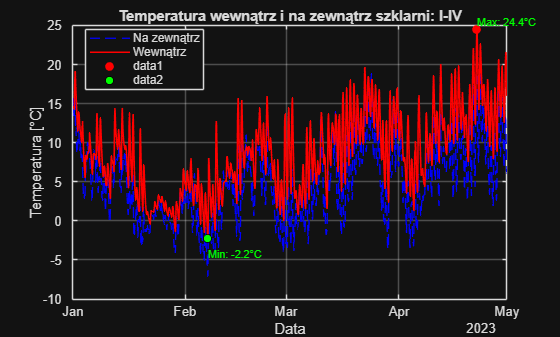



% --- wykres I-IV
idx_1 = month(T.time) <5;         
T_1 = T(idx_1,:);

figure;
plot(T_1.time, T_1.temp_zew, 'b--', 'LineWidth', 1.0); hold on;
plot(T_1.time, T_1.Tin, 'r', 'LineWidth', 1.2);
grid on;

xlabel('Data');
ylabel('Temperatura [°C]');
title('Temperatura wewnątrz i na zewnątrz szklarni: I-IV');
legend('Na zewnątrz', 'Wewnątrz', 'Location', 'best');

% --- minimalna i maksymalna temperatura wewnątrz 
Tmin = min(T_1.Tin);
Tmax = max(T_1.Tin);
Tmin_time = T_1.time(T_1.Tin == Tmin);
Tmax_time = T_1.time(T_1.Tin == Tmax);

plot(Tmax_time, Tmax, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
plot(Tmin_time, Tmin, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 6);

text(Tmax_time, Tmax + 1, sprintf('Max: %.1f°C', Tmax), 'Color', 'g', 'FontSize', 8);
text(Tmin_time, Tmin - 2, sprintf('Min: %.1f°C', Tmin), 'Color', 'g', 'FontSize', 8);


fprintf('STYCZEŃ-KWIECIEŃ — temperatura wewnątrz szklarni:\n');

STYCZEŃ-KWIECIEŃ — temperatura wewnątrz szklarni:


fprintf('  Min = %.2f °C (%s)\n', Tmin, string(Tmin_time(1)));

  Min = -2.23 °C (07-Feb-2023 07:10:00)


fprintf('  Max = %.2f °C (%s)\n', Tmax, string(Tmax_time(1)));

  Max = 24.43 °C (22-Apr-2023 16:10:00)


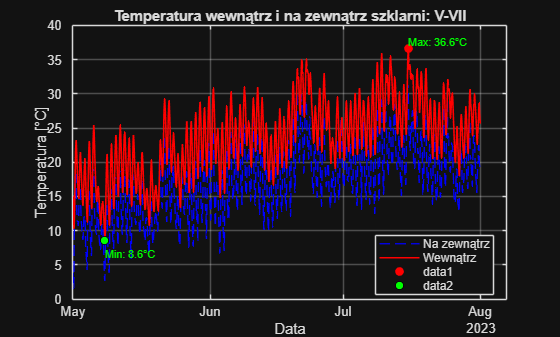



% --- wykres V-VII
idx_2 = (month(T.time) > 4) & (month(T.time) < 8);         
T_2 = T(idx_2,:);
figure;
plot(T_2.time, T_2.temp_zew, 'b--', 'LineWidth', 1.0); hold on;
plot(T_2.time, T_2.Tin, 'r', 'LineWidth', 1.2);
grid on;

xlabel('Data');
ylabel('Temperatura [°C]');
title('Temperatura wewnątrz i na zewnątrz szklarni: V-VII');
legend('Na zewnątrz', 'Wewnątrz', 'Location', 'best');

% --- minimalna i maksymalna temperatura wewnątrz 
Tmin2 = min(T_2.Tin);
Tmax2 = max(T_2.Tin);
Tmin_time2 = T_2.time(T_2.Tin == Tmin2);
Tmax_time2 = T_2.time(T_2.Tin == Tmax2);

plot(Tmax_time2, Tmax2, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
plot(Tmin_time2, Tmin2, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 6);

text(Tmax_time2, Tmax2 + 1, sprintf('Max: %.1f°C', Tmax2), 'Color', 'g', 'FontSize', 8);
text(Tmin_time2, Tmin2 - 2, sprintf('Min: %.1f°C', Tmin2), 'Color', 'g', 'FontSize', 8);


fprintf('MAJ - SIERPIEŃ — temperatura wewnątrz szklarni:\n');

MAJ - SIERPIEŃ — temperatura wewnątrz szklarni:


fprintf('  Min = %.2f °C (%s)\n', Tmin2, string(Tmin_time2(1)));

  Min = 8.58 °C (08-May-2023 05:10:00)


fprintf('  Max = %.2f °C (%s)\n', Tmax2, string(Tmax_time2(1)));

  Max = 36.62 °C (15-Jul-2023 17:10:00)


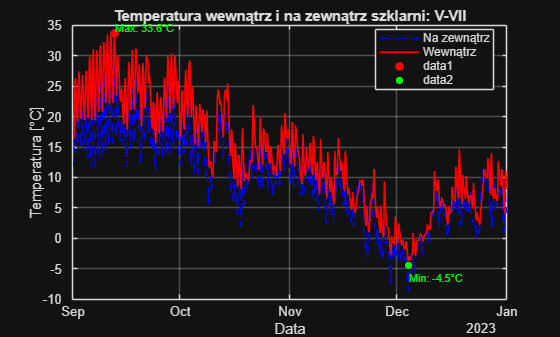


% --- wykres IX-XII
idx_3 = (month(T.time) > 8) & (month(T.time) < 13);         
T_3 = T(idx_3,:);
figure;
plot(T_3.time, T_3.temp_zew, 'b--', 'LineWidth', 1.0); hold on;
plot(T_3.time, T_3.Tin, 'r', 'LineWidth', 1.2);
grid on;

xlabel('Data');
ylabel('Temperatura [°C]');
title('Temperatura wewnątrz i na zewnątrz szklarni: V-VII');
legend('Na zewnątrz', 'Wewnątrz', 'Location', 'best');

% --- minimalna i maksymalna temperatura wewnątrz 
Tmin3 = min(T_3.Tin);
Tmax3 = max(T_3.Tin);
Tmin_time3 = T_3.time(T_3.Tin == Tmin3);
Tmax_time3 = T_3.time(T_3.Tin == Tmax3);

plot(Tmax_time3, Tmax3, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
plot(Tmin_time3, Tmin3, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 6);

text(Tmax_time3, Tmax3 + 1, sprintf('Max: %.1f°C', Tmax3), 'Color', 'g', 'FontSize', 8);
text(Tmin_time3, Tmin3 - 2, sprintf('Min: %.1f°C', Tmin3), 'Color', 'g', 'FontSize', 8);


fprintf('WRZESIEŃ - GRZUDZIEŃ — temperatura wewnątrz szklarni:\n');

WRZESIEŃ - GRZUDZIEŃ — temperatura wewnątrz szklarni:


fprintf('  Min = %.2f °C (%s)\n', Tmin3, string(Tmin_time3(1)));

  Min = -4.55 °C (04-Dec-2023 08:10:00)


fprintf('  Max = %.2f °C (%s)\n', Tmax3, string(Tmax_time3(1)));

  Max = 33.61 °C (12-Sep-2023 16:10:00)


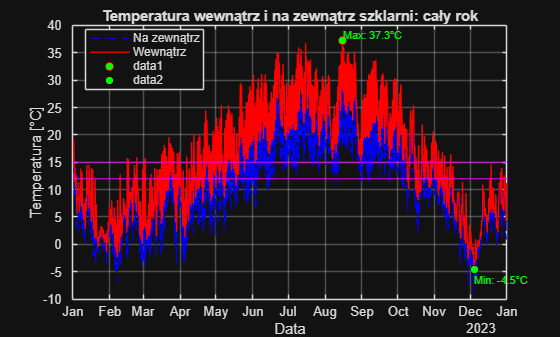




% --- wykres: cały rok
figure;
plot(T.time, T.temp_zew, 'b--', 'LineWidth', 0.8); hold on;
plot(T.time, T.Tin,      'r',   'LineWidth', 1);
grid on;

yline(12, 'm', 'LineWidth', 1.0);
yline(15, 'm', 'LineWidth', 1.0);

xlabel('Data');
ylabel('Temperatura [°C]');
title('Temperatura wewnątrz i na zewnątrz szklarni: cały rok');
legend('Na zewnątrz', 'Wewnątrz', 'Location', 'best');

% --- minimalna i maksymalna temperatura wewnątrz w ciągu roku
Tmin_all = min(T.Tin);
Tmax_all = max(T.Tin);

idx_min_all = (T.Tin == Tmin_all);
idx_max_all = (T.Tin == Tmax_all);

Tmin_time_all = T.time(idx_min_all);
Tmax_time_all = T.time(idx_max_all);

plot(Tmax_time_all, Tmax_all, 'ro', 'MarkerFaceColor', 'g', 'MarkerSize', 6);
plot(Tmin_time_all, Tmin_all, 'ko', 'MarkerFaceColor', 'g', 'MarkerSize', 6);

text(Tmax_time_all(1), Tmax_all + 1, ...
     sprintf('Max: %.1f°C', Tmax_all), 'Color', 'g', 'FontSize', 8);
text(Tmin_time_all(1), Tmin_all - 2, ...
     sprintf('Min: %.1f°C', Tmin_all), 'Color', 'g', 'FontSize', 8);


fprintf('CAŁY ROK — temperatura wewnątrz szklarni:\n');

CAŁY ROK — temperatura wewnątrz szklarni:


fprintf('  Min = %.2f °C (%s)\n', Tmin_all, string(Tmin_time_all(1)));

  Min = -4.55 °C (04-Dec-2023 08:10:00)


fprintf('  Max = %.2f °C (%s)\n', Tmax_all, string(Tmax_time_all(1)));

  Max = 37.28 °C (15-Aug-2023 16:10:00)





T.UA_v = T.U_v_act*A_g;
UA_env = T.U_act*A_s + T.U_p_act*A_p + T.U_d_act*A_d + U_l*A_c;
fprintf('UA_env (średnie): %.1f W/K\n', mean(UA_env));

UA_env (średnie): 905.0 W/K


fprintf('UA_v (max):       %.1f W/K\n', max(T.UA_v));

UA_v (max):       1897.9 W/K


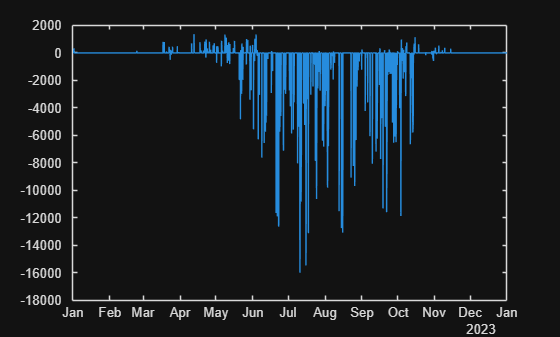


%wentylacja
figure;
plot(T.time, T.Q_vent_act);

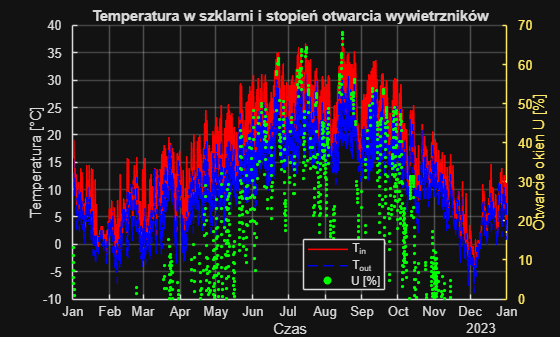


%kiedy działa wentylacja
figure; hold on; grid on;
plot(T.time, T.Tin,  'r-', 'LineWidth', 1.2);
plot(T.time, T.temp_zew, 'b--','LineWidth', 1.0);
yyaxis right
idx_open = T.U_act>0;
scatter(T.time(idx_open), T.U_act(idx_open)*100, 6, 'g','filled');
ylabel('Otwarcie okien U [%]');

yyaxis left
xlabel('Czas');
ylabel('Temperatura [°C]');
title('Temperatura w szklarni i stopień otwarcia wywietrzników');
legend('T_{in}','T_{out}','U [%]','Location','best');

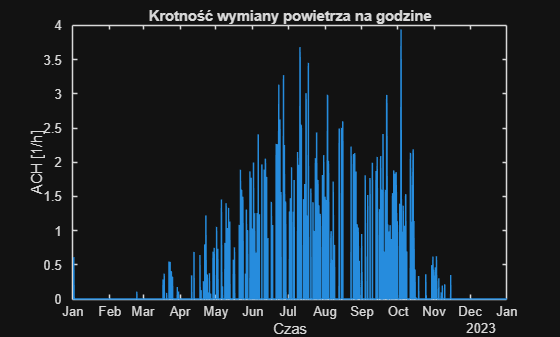




%ACH (zmiana powietrza w ciągu 1 h)
ACH = T.G_vent_act ./ V * dt;   


figure; grid on;
plot(T.time, ACH);
xlabel('Czas');
ylabel('ACH [1/h]');
title('Krotność wymiany powietrza na godzine')

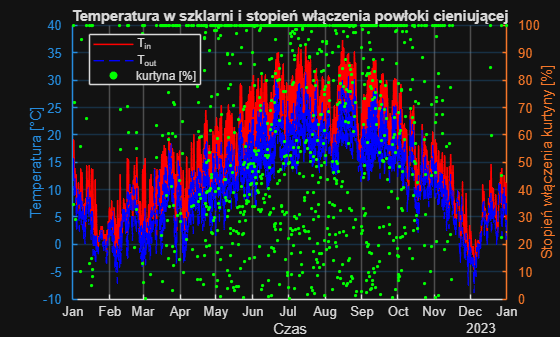



%stopień włączenia powłoki cieniującej
f_shade = (1 - T.tau_eff ./ tau_base) / (1 - tau_4);
f_shade = max(0, min(1, f_shade)); 
idx_shade = f_shade > 0;
figure; hold on; grid on;

yyaxis left
plot(T.time, T.Tin,      'r-',  'LineWidth', 1.2);
plot(T.time, T.temp_zew, 'b--', 'LineWidth', 1.0);
ylabel('Temperatura [°C]');

yyaxis right
scatter(T.time(idx_shade), f_shade(idx_shade)*100, 6, 'g','filled');
ylabel('Stopień włączenia kurtyny [%]');

xlabel('Czas');
title('Temperatura w szklarni i stopień włączenia powłoki cieniującej');
legend('T_{in}','T_{out}','kurtyna [%]','Location','best');

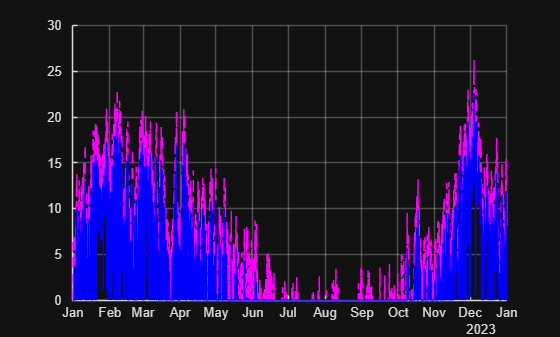



% o ile możemy przechłodzić/przegrzać żeby nie wyjść poza zakres


figure; hold on;
plot(T.time, T.Q_h_15/1000, 'm--');
plot(T.time, T.Q_h_act/1000, 'b');
grid on;

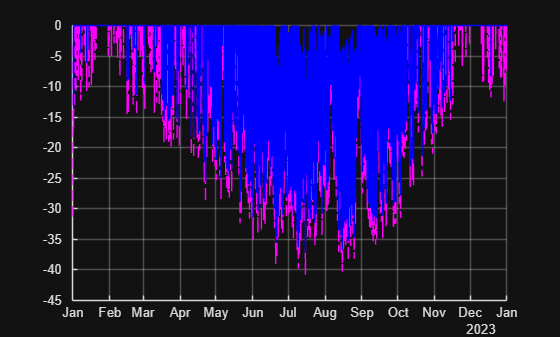


figure; hold on;
plot(T.time, -T.Q_c_12/1000, 'm--');
plot(T.time, -T.Q_c_act/1000, 'b');
grid on;

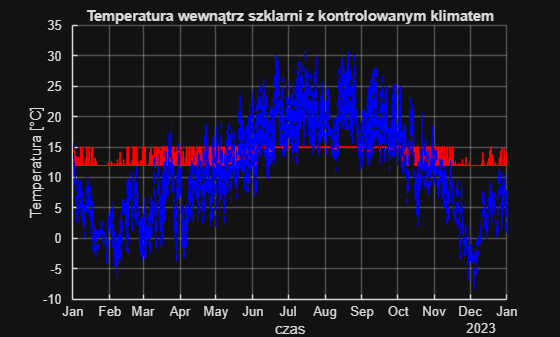




%% --------------- ZAPOTRZEBOWANIE CIEPLNE



% W - W/m2
T.q_heat = T.Q_h_act/A_g;
T.q_cool = T.Q_c_act/A_g;


%wykres temperatur w szklarni z kontrolowanym klimatem

figure; grid on; hold on;
plot(T.time, T.Tin_active,      'r-',  'LineWidth', 1.2);
plot(T.time, T.temp_zew, 'b--', 'LineWidth', 1.0);
xlabel('czas'); ylabel('Temperatura [°C]')
title('Temperatura wewnątrz szklarni z kontrolowanym klimatem')

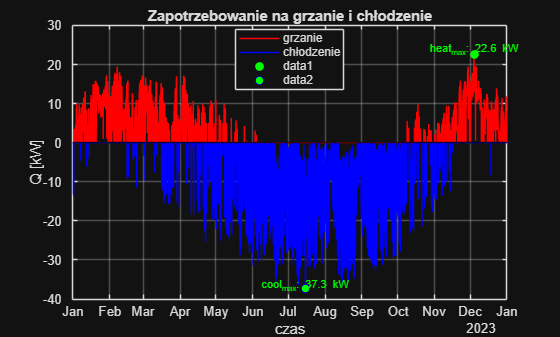


% --- wykres zapotrzebowania na grzanie i chłodzenie + maxima z funckji[W]
figure; hold on; box on; grid on

% krzywe czasowe
plot(T.time, T.Q_h_act/1000, 'r-');
plot(T.time, -T.Q_c_act/1000, 'b-');

yline(0,'k-');    
xlabel('czas'); ylabel('Q [kW]');
title('Zapotrzebowanie na grzanie i chłodzenie');
legend('grzanie','chłodzenie','Location','best');

% --- maksimum GRZANIA
[Q_heat_peak, idx_h] = max(T.Q_h_act);      % [W]
t_heat_peak = T.time(idx_h);

plot(t_heat_peak, Q_heat_peak/1000,'o','MarkerFaceColor','g', 'MarkerEdgeColor', 'g', 'MarkerSize', 6);

text(t_heat_peak, Q_heat_peak/1000*1.05 , ...
     sprintf('heat_{max}: %.1f kW', Q_heat_peak/1000),'Color','g', 'FontSize', 8, 'HorizontalAlignment','center');

% --- maksimum CHŁODZENIA
[Q_cool_peak, idx_c] = max(T.Q_c_act);      % [W]
t_cool_peak = T.time(idx_c);

plot(t_cool_peak, -Q_cool_peak/1000, 'o','MarkerFaceColor','g', 'MarkerEdgeColor', 'b', 'MarkerSize', 6);

text(t_cool_peak, -Q_cool_peak/1000*0.98, ...
     sprintf('cool_{max}: %.1f kW', Q_cool_peak/1000),'Color', 'g', 'FontSize', 8, 'HorizontalAlignment','center');


fprintf('Maksymalne zapotrzebowanie na grzanie:    %.2f kW (%s)\n', ...
        Q_heat_peak/1000, string(t_heat_peak));

Maksymalne zapotrzebowanie na grzanie:    22.62 kW (04-Dec-2023 07:10:00)


fprintf('Maksymalne zapotrzebowanie na chłodzenie: %.2f kW (%s)\n', ...
        Q_cool_peak/1000, string(t_cool_peak));

Maksymalne zapotrzebowanie na chłodzenie: 37.30 kW (15-Jul-2023 11:10:00)


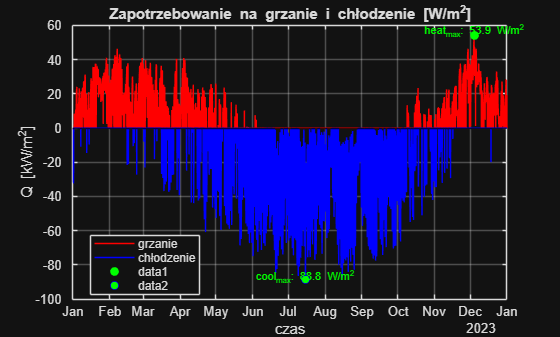






% --- wykres zapotrzebowania na grzanie i chłodzenie + maxima [W/m2]
figure; hold on; box on; grid on

% krzywe czasowe
plot(T.time,  T.q_heat, 'Color','r');   % grzanie [W/m2]
plot(T.time, -T.q_cool, 'Color','b');   % chłodzenie [W/2]


yline(0,'k-');    
xlabel('czas'); ylabel('Q [kW/m^{2}]');
title('Zapotrzebowanie na grzanie i chłodzenie [W/m^{2}]');
legend('grzanie','chłodzenie','Location','best');

% --- maksimum GRZANIA
[q_heat_peak, idx_hq] = max(T.q_heat);      % [W/m2]
tq_heat_peak = T.time(idx_hq);

plot(tq_heat_peak, q_heat_peak,'o','MarkerFaceColor','g', 'MarkerEdgeColor', 'g', 'MarkerSize', 6);

text(tq_heat_peak, q_heat_peak*1.05, ...
     sprintf('heat_{max}: %.1f W/m^{2}', q_heat_peak),'Color','g', 'FontSize', 8, 'HorizontalAlignment','center');

% --- maksimum CHŁODZENIA
[q_cool_peak, idx_cq] = max(T.q_cool);      % [W/m2]
tq_cool_peak = T.time(idx_cq);

plot(tq_cool_peak, -q_cool_peak, 'o','MarkerFaceColor','g', 'MarkerEdgeColor', 'b', 'MarkerSize', 6);

text(tq_cool_peak, -q_cool_peak *0.98, ...
     sprintf('cool_{max}: %.1f W/m^{2}', q_cool_peak),'Color', 'g', 'FontSize', 8, 'HorizontalAlignment','center');


fprintf('Maksymalne zapotrzebowanie na grzanie:    %.2f W/m^{2} (%s)\n', ...
        q_heat_peak, string(tq_heat_peak));

Maksymalne zapotrzebowanie na grzanie:    53.86 W/m^{2} (04-Dec-2023 07:10:00)


fprintf('Maksymalne zapotrzebowanie na chłodzenie: %.2f W/m^{2} (%s)\n', ...
        q_cool_peak, string(tq_cool_peak));

Maksymalne zapotrzebowanie na chłodzenie: 88.83 W/m^{2} (15-Jul-2023 11:10:00)


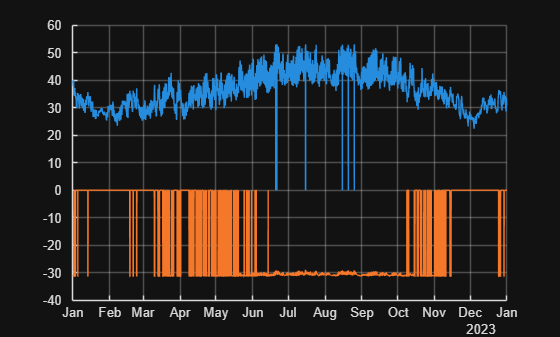






%% --------- dobór PCM  + pompy ciepła

%minimalna i maksymalna temperatura zewnetrzna dla chłodzenia
mask_c = Q_c_act > 0;               
idx_all_c = find(mask_c);

[~, i_min_c] = min(T.temp_zew(mask_c)); 
idx_c_min = idx_all_c(i_min_c);            
temp_zew_min_c = T.temp_zew(idx_c_min);  
time_min_c      = T.time(idx_c_min);      

[~, i_max_c] = max(T.temp_zew(mask_c)); 
idx_c_max = idx_all_c(i_max_c);            
temp_zew_max_c = T.temp_zew(idx_c_max);  
time_max_c      = T.time(idx_c_max); 
Q_c_max_c = Q_c_act(idx_c_max)/1000; 



%minimalna i maksymalna temperatura zewnetrzna dla grzania
mask_h = Q_h_act > 0;               
idx_all_h = find(mask_h);

[~, i_min_h] = min(T.temp_zew(mask_h)); 
idx_h_min = idx_all_h(i_min_h);            
temp_zew_min_h = T.temp_zew(idx_h_min);  
time_min_h      = T.time(idx_h_min);    
Q_h_min_h = Q_h_act(idx_h_min)/1000; 

[~, i_max_h] = max(T.temp_zew(mask_h)); 
idx_h_max = idx_all_h(i_max_h);            
temp_zew_max_h = T.temp_zew(idx_h_max);  
time_max_h      = T.time(idx_h_max); 
Q_h_max_h = Q_h_act(idx_h_max)/1000; 


function [Q_HP_h, P_el_HP, COP_HP] = HP_heat(Tamb)
% tryb GRZANIA dla ZHI27K1P-TFD
% Stałe założenia:
% Tc = 40°C,  Te = Tamb - dT_evap_air,  dT_evap_air = 5 K

    Tamb = Tamb(:);

    % --- dane katalogowe, Tc = 40°C
    Te_tab = [ ...
    -30  -25  -20  -15  -10  -5   0   5   7  10  12.5  15  20  25];  % [°C]

    Qevap_tab_kW =  [ ...
     7.88, 10.10, 12.55, 15.30, 18.35, 21.70, ...
    25.30, 29.30, 31.00, 33.60, 35.80, 38.20, 43.10, 48.50];

    Pel_tab_kW   = [ ...
     6.28,  6.30,  6.33,  6.36,  6.36,  6.33, ...
     6.25,  6.12,  6.04,  5.90,  5.77,  5.61,  5.21,  4.70];

    dT_evap_air = 5;                   % [K]
    Te = Tamb - dT_evap_air;           % [°C]

    % interpolacja po Te 
    Qevap_W = interp1(Te_tab, Qevap_tab_kW, Te, 'linear', 'extrap') * 1e3;
    Pel_W   = interp1(Te_tab, Pel_tab_kW,   Te, 'linear', 'extrap') * 1e3;

    % ograniczenie envelope
    Te_min = -30;
    Te_max =  25;
    outside = (Te < Te_min) | (Te > Te_max);

    Qevap_W(outside) = 0;
    Pel_W(outside)   = 0;

    % moc grzewcza na skraplaczu + COP
    Qcond_W = Qevap_W + Pel_W;   % [W]

    COP = NaN(size(Qcond_W));
    idx = Pel_W > 0;
    COP(idx) = Qcond_W(idx) ./ Pel_W(idx);

    Q_HP_h  = Qcond_W;
    P_el_HP = Pel_W;
    COP_HP  = COP;
end






function [Q_HP_c, P_el_HP, COP_HP] = HP_cool(Tamb)
% tryb CHŁODZENIA dla ZHI27K1P-TFD
% Stałe założenia:
% Te = 5°C (kolumna w tabeli), Tc = Tamb + dT_cond_air, dT_cond_air = 10 K

    Tamb = Tamb(:);

    % dane katalogowe, Te = 5°C 
    Tc_tab = [ ...
     20  25  30  35  40  45  50  55  60  65  68];   % [°C]

    Qevap_tab_kW = [ ...
    31.50, 31.10, 30.70, 30.00, 29.30, ...
    28.40, 27.40, 26.30, 25.10, 23.80, 23.00];

    Pel_tab_kW = [ ...
     3.28,  3.96,  4.64,  5.35,  6.12, ...
     6.97,  7.94,  9.01, 10.35, 11.80, 12.80];

    dT_cond_air = 10;                 % [K]
    Tc = Tamb + dT_cond_air;          % [°C]

    % interpolacja po Tc 
    Qevap_W = interp1(Tc_tab, Qevap_tab_kW, Tc, 'linear', 'extrap') * 1e3;
    Pel_W   = interp1(Tc_tab, Pel_tab_kW,   Tc, 'linear', 'extrap') * 1e3;

    % ograniczenie envelope
    Tc_max = 68;
    Tc_min = 20;
    outside = (Tc < Tc_min) | (Tc > Tc_max);

    Qevap_W(outside) = 0;
    Pel_W(outside)   = 0;

    % COP chłodzenia
    COP = NaN(size(Qevap_W));
    idx = Pel_W > 0;
    COP(idx) = Qevap_W(idx) ./ Pel_W(idx);

    Q_HP_c  = Qevap_W;
    P_el_HP = Pel_W;
    COP_HP  = COP;
end


[Q_HP_h_nom, P_el_HP_heat, COP_HP_heat] = HP_heat(T.temp_zew);

[Q_HP_c_nom, P_el_HP_cool, COP_HP_cool] = HP_cool(T.temp_zew);

figure; hold on; grid on;
plot(T.time, Q_HP_h_nom/1000);
plot(T.time, -Q_HP_c_nom/1000);




J2Wh = 1/dt;

%% Dane PCM 
t_m    = 12;         % [°C] temperatura topnienia PCM 
l_pcm  = 200000;     % [J/kg] cieplo przemiany fazowej PCM
rho_pcm = 803;       % [kg/m3] gestosc PCM

%% Woda 
t_w1 = 8;           % [°C] temperatura poczatkowa wody 
t_w2 = 15;           % [°C] temperatura koncowa wody
dt_w = t_w2 - t_w1;  % [K]
cp_w  = 4190.71;     % [J/(kg K)] cieplo wlasciwe wody
rho_w = 999.31;      % [kg/m3] gestosc wody

%% Zapotrzebowanie chlodnicze
f = 1.2;                  % udzial szczytu
P_PCM = Q_cool_peak * f;     % [W] moc pokrywana z magazynu PCM
t_store = 3600;              % [s] czas trwania szczytu (1 h)
Q_req = P_PCM * t_store;     % [J] wymagana energia w czasie szczytu

%% Parametry magazynu 
pf        = 0.95;     % udzial objetosciowy PCM
Vtank_min = 0.1;      % [m3] dolne ograniczenie objetosci
Vtank_max = 100;      % [m3] gorne ograniczenie objetosci


% Gestosc energii na 1 m3 magazynu (PCM + woda)
Q_per_m3 = (1 - pf)*rho_w*cp_w*dt_w+(pf)*rho_pcm*l_pcm;  % [J/m3]
Q_per_m3_Wh = Q_per_m3 *J2Wh;                           % [Wh/m3] 

fprintf('Gestosc energii magazynu: %.2f kWh/m3\n', Q_per_m3_Wh/1000);

Gestosc energii magazynu: 42.79 kWh/m3



%% GENETIC ALGORITHM 
nvars = 1;                         % 1 zmienna decyzyjna: Vtank
lb    = Vtank_min;                 % dolne ograniczenie
ub    = Vtank_max;                 % gorne ograniczenie

% Funkcja fitness 
fitnessFcn = @(x) pcmFitness(x, Q_req, Q_per_m3);

% Ustawienia GA (
opts = optimoptions('ga', ...
    'PopulationSize', 50, ...
    'MaxGenerations', 100, ...
    'Display', 'iter');

%% Uruchomienie GA -------------------------------------------------------
[Vtank_opt, output] = ga(fitnessFcn, nvars, [], [], [], [], lb, ub, [], opts);


Single objective optimization:
1 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100           2.876        1.65e+04        0
    2              147           1.876           19.81        0
    3              194           1.876           537.5        1
    4              241           1.376           6.629        0
    5              288           1.376            2112        1
    6              335           1.376           528.9        2
    7              382           1.126           1.711        0
    8              429           1.126           528.7        1
    9              476           1.126            1056        2
   10              523           1.126           148.2        3
   11        


%% Wyniki optymalizacji --------------------------------------------------
Vtank = Vtank_opt;                   % [m3] optymalna objetosci zbiornika
V_pcm = pf * Vtank;                  % [m3] objetosci PCM
V_w   = (1 - pf) * Vtank;            % [m3] objetosci wody

m_pcm = rho_pcm * V_pcm;             % [kg]
m_w   = rho_w   * V_w;               % [kg]

Q_store = Vtank * Q_per_m3;          % [J] energia magazynowana
P_density = P_PCM / Vtank/ 1000;     % [kW/m3] gestosc mocy magazynu

fprintf('\n--- WYNIKI GA ---\n');


--- WYNIKI GA ---


fprintf('Q_req        = %.3e J (%.2f kWh)\n', Q_req, Q_req/3.6e6);

Q_req        = 1.611e+08 J (44.76 kWh)


fprintf('Vtank_opt    = %.3f m3\n', Vtank);

Vtank_opt    = 1.046 m3


fprintf('V_pcm        = %.3f m3  -> m_pcm = %.1f kg\n', V_pcm, m_pcm);

V_pcm        = 0.994 m3  -> m_pcm = 798.1 kg


fprintf('V_w          = %.3f m3  -> m_w   = %.1f kg\n', V_w, m_w);

V_w          = 0.052 m3  -> m_w   = 52.3 kg


fprintf('Q_store      = %.3e J (%.2f kWh)\n', Q_store, Q_store/3.6e6);

Q_store      = 1.611e+08 J (44.76 kWh)


fprintf('P_density    = %.1f kW/m3\n', P_density);

P_density    = 42.8 kW/m3


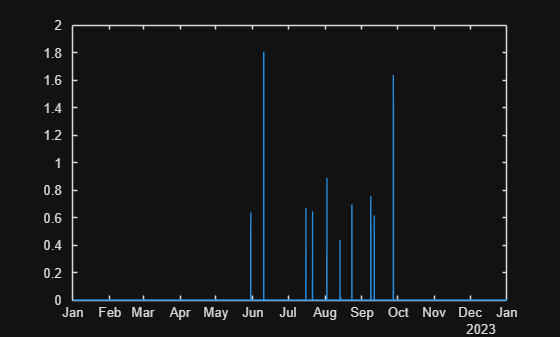


%% Funkcja fitness -----------------------------------------------------
function F = pcmFitness(x, Q_req, Q_per_m3)
    % x(1) = Vtank [m3]
    Vtank = x(1);

    % Energia, jaka moze zmagazynowac zbiornik
    Q_store = Vtank * Q_per_m3;   % [J]

    % Niedobor energii, jesli Q_store < Q_req
    deficit = max(0, Q_req - Q_store);

    penalty = (deficit / max(Q_req, eps))^2;
    alpha   = 1e6;   % wspolczynnik kary

    F = Vtank + alpha * penalty;
end

Q_store_Wh = Q_store / dt;   % pojemność magazynu




%  -------------- sterowanie PCM + HP -------------

Q_h_15_dem = T.Q_h_15;
Q_c_12_dem = T.Q_c_12;

Q_heat_dem = T.Q_h_act;
Q_cool_dem = T.Q_c_act;
Q_dem_net  = T.Q_h_act - T.Q_c_act;

% Ile energii w danym kroku [Wh]
Q_heat_PCM = zeros(n,1);   % energia oddana do ogrzewania


% --- zmienne czasowe -----------------------------------------
E_PCM        = zeros(n,1);
E_PCM(1)     = 0.5 * Q_store_Wh;  % start od 50%

Q_heat_HP    = zeros(n,1);  % [Wh] – grzanie do szklarni z HP
Q_heat_dump  = zeros(n,1);  % [Wh] – (CWU/odrzut)

Q_cool_HP    = zeros(n,1);  % [Wh] – chłodzenie szklarni z HP
Q_cool_PCM   = zeros(n,1);  % [Wh] – chłód z PCM do szklarni
Q_charge_PCM = zeros(n,1);  % [Wh] – ładowanie PCM zimnem
Q_cool_unmet = zeros(n,1);  % [Wh] – niepokryte chłodzenie
Q_cool_over  = zeros(n,1);  % [Wh] – NADMIAR chłodu HP, którego nie da się zmagazynować
Q_heat_PCM   = zeros(n,1);
Q_heat_unmet = zeros(n,1);

dt_h = 1;            % [h] – krok godzinowy

% --- nastawy ---
SOC_min_peak = 0.0;     % awaryjne minimum
SOC_min_base = 0.18;    % normalna rezerwa PCM
margin_PCM   = 1.3;     
SOC_precharge = 0.9;   % docelowe naładowanie PCM podczas grzania
SOC_min_heat = 0.7;    % minimalny SOC zostawiany na sytuacje krytyczne

% -------------------------------------------------------

for k = 1:n

    if k > 1
        E_PCM(k) = E_PCM(k-1);
    end

    Qh_dem = max(Q_heat_dem(k), 0) * dt_h;   % [Wh]
    Qc_dem = max(Q_cool_dem(k), 0) * dt_h;   % [Wh]

    Q_HP_h_step = max(Q_HP_h_nom(k), 0) * dt_h;  % [Wh]
    Q_HP_c_step = max(Q_HP_c_nom(k), 0) * dt_h;  % [Wh]
% 1) GRZANIE 
if (Qh_dem > 0) && (Qc_dem == 0)

    % Maksymalna energia grzewcza HP w tej godzinie
    Q_HP_h_avail = Q_HP_h_step;             % [Wh]

    % PRZYPADEK A: HP WYSTARCZA LUB MA NADWYŻKĘ 
    if Q_HP_h_avail >= Qh_dem

        % Ile chcemy mieć w PCM?
        SOC_now   = E_PCM(k) / Q_store_Wh;
        E_target  = SOC_precharge * Q_store_Wh;      
        E_deficit = max(E_target - E_PCM(k), 0);     % [Wh] brak do SOC_precharge

        % Maksymalna energia na PCM, NIE uszczuplając Qh_dem
        Q_for_PCM_max = max(Q_HP_h_avail - Qh_dem, 0);   % [Wh]

        % faktyczne ładowanie PCM:
        Q_pre_cold = min(E_deficit, Q_for_PCM_max);      % [Wh]

        % Aktualizacja PCM
        Q_charge_PCM(k) = Q_pre_cold;
        E_PCM(k)        = E_PCM(k) + Q_pre_cold;

        % Grzanie szklarni z pozostałej mocy 
        Q_HP_h_for_heat = Q_HP_h_avail - Q_pre_cold;     % [Wh]

        Q_heat_HP(k)    = min(Qh_dem, Q_HP_h_for_heat);  % [Wh]
        Q_heat_PCM(k)   = 0;
        Q_heat_unmet(k) = 0;

        % Nadwyżka na CWU / odrzut
        Q_heat_dump(k)  = max(Q_HP_h_for_heat - Q_heat_HP(k), 0);

    % PRZYPADEK B: HP ZA SŁABA -> DOGRZEWANIE Z PCM 
    else

        % HP daje wszystko co ma
        Q_heat_HP(k)   = Q_HP_h_avail;      % [Wh]
        Q_heat_dump(k) = 0;                 % nic nie wyrzucamy

        % Deficyt grzewczy
        deficit = Qh_dem - Q_HP_h_avail;    % [Wh]

        % Cała energia z PCM dostępna na dogrzanie
        E_avail_heat = max(E_PCM(k), 0);    % [Wh]

        Q_from_PCM   = min(deficit, E_avail_heat);  % [Wh]

        Q_heat_PCM(k) = Q_from_PCM;
        E_PCM(k)      = E_PCM(k) - Q_from_PCM;

        % Ewentualnie niepokryta reszta
        Q_heat_unmet(k) = deficit - Q_from_PCM;     % [Wh]

        % W tym wariancie NIE ładujemy PCM
        Q_charge_PCM(k) = 0;
    end

    % W trybie grzania nic nie chłodzimy 
    Q_cool_HP(k)    = 0;
    Q_cool_PCM(k)   = 0;
    Q_cool_unmet(k) = 0;
    Q_cool_over(k)  = 0;

    % 2) CHŁODZENIE 
  elseif (Qc_dem > 0) && (Qh_dem == 0)

        Qc_dem_W = max(Q_cool_dem(k), 0);    % [W]
        Qc_dem   = Qc_dem_W * dt_h;          % [Wh]

        SOC = E_PCM(k) / Q_store_Wh;


        % 2A: PCM solo (HP OFF), tylko gdy serio ma zapas 
        E_min_base   = SOC_min_base * Q_store_Wh;
        E_avail_base = max(E_PCM(k) - E_min_base, 0);   % [Wh]
        need_PCM_only = margin_PCM * Qc_dem;            % [Wh]

        if (E_avail_base >= need_PCM_only)
            % PCM pokrywa całą godzinę, HP wyłączona
            Q_cool_HP(k)    = 0;
            Q_cool_PCM(k)   = Qc_dem;
            E_PCM(k)        = E_PCM(k) - Qc_dem;

            Q_charge_PCM(k) = 0;
            Q_cool_unmet(k) = 0;
            Q_cool_over(k)  = 0;
            Q_heat_HP(k)    = 0;
            Q_heat_dump(k)  = 0;

        % 2B: HP ON (zawsze gdy PCM-solo nie wystarcza) 
        else

            Q_HP_c_avail = Q_HP_c_step;   % pełna moc nominalna HP

            % 2B.1 HP >= zapotrzebowanie
            if Q_HP_c_avail >= Qc_dem

                Q_cool_HP(k) = Qc_dem;               % do szklarni
                surplus      = Q_HP_c_avail - Qc_dem;
                cap          = Q_store_Wh - E_PCM(k);

                Q_charge        = min(surplus, max(cap,0));
                Q_charge_PCM(k) = Q_charge;
                E_PCM(k)        = E_PCM(k) + Q_charge;

                Q_cool_PCM(k)   = 0;
                Q_cool_unmet(k) = 0;
                Q_cool_over(k)  = surplus - Q_charge;

            % 2B.2 HP < zapotrzebowanie 
            else
                % Najpierw HP daje wszystko co ma
                Q_cool_HP(k) = Q_HP_c_avail;
                deficit      = Qc_dem - Q_HP_c_avail;    % [Wh]

                % KROK 1: PCM tylko do SOC_min_base
                E_min_norm   = SOC_min_base * Q_store_Wh;
                E_avail_norm = max(E_PCM(k) - E_min_norm, 0);
                Q_from_norm  = min(deficit, E_avail_norm);

                Q_cool_PCM(k) = Q_from_norm;
                E_PCM(k)      = E_PCM(k) - Q_from_norm;
                deficit_left  = deficit - Q_from_norm;

                % KROK 2: jeśli nadal brakuje -> sięgamy po rezerwę
               
                if deficit_left > 0
                    E_min_res   = SOC_min_peak * Q_store_Wh;
                    E_avail_res = max(E_PCM(k) - E_min_res, 0);
                    Q_from_res  = min(deficit_left, E_avail_res);

                    Q_cool_PCM(k) = Q_cool_PCM(k) + Q_from_res;
                    E_PCM(k)      = E_PCM(k) - Q_from_res;

                    deficit_left  = deficit_left - Q_from_res;
                end

                Q_cool_unmet(k) = deficit_left;   
                Q_charge_PCM(k) = 0;
                Q_cool_over(k)  = 0;
            end

            Q_heat_HP(k)   = 0;
            Q_heat_dump(k) = 0;
        end
    end
end







figure;
plot(T.time, Q_cool_over/1000);

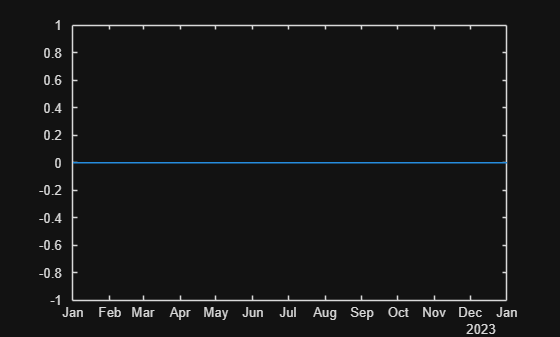


figure;
plot(T.time, Q_cool_unmet/1000);

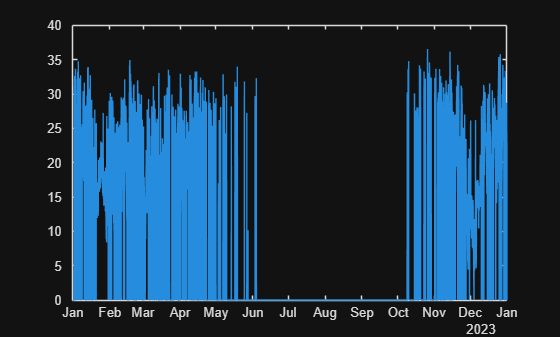



figure;
plot(T.time, Q_heat_dump/1000);


figure;
plot(T.time, Q_heat_unmet/1000);


dt_h = 1;

idx_cool = Q_cool_dem > 0;

E_HP_kWh     = sum(Q_HP_c_nom(idx_cool))*dt_h/1000;
E_dem_kWh    = sum(Q_cool_dem(idx_cool))*dt_h/1000;
E_over_kWh   = sum(Q_cool_over(idx_cool))/1000;

fprintf('Chłód potencjalnie z HP:      %.1f kWh\n', E_HP_kWh);

Chłód potencjalnie z HP:      103482.6 kWh


fprintf('Zapotrzebowanie szklarni:     %.1f kWh\n', E_dem_kWh);

Zapotrzebowanie szklarni:     43160.9 kWh


fprintf('Nadmiar wg modelu (over):     %.1f kWh\n', E_over_kWh);

Nadmiar wg modelu (over):     10.9 kWh


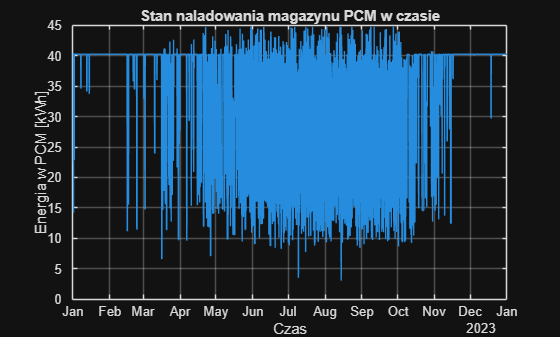





%% stan naladowania magazynu PCM
figure;
plot(T.time, E_PCM/1000);   % kWh
grid on;
xlabel('Czas');
ylabel('Energia w PCM [kWh]');
title('Stan naladowania magazynu PCM w czasie');



E_min = min(E_PCM);      % [Wh]
E_max = max(E_PCM);      % [Wh]
dyn_range = E_max - E_min;       
util = dyn_range / Q_store_Wh;

fprintf('E_min = %.1f kWh\n', E_min/1000);

E_min = 3.0 kWh


fprintf('E_max = %.1f kWh\n', E_max/1000);

E_max = 44.8 kWh


fprintf('Zakres pracy = %.1f kWh (%.4f %% pojemności)\n', ...
        dyn_range/1000, 100*util);

Zakres pracy = 41.7 kWh (93.2590 % pojemności)


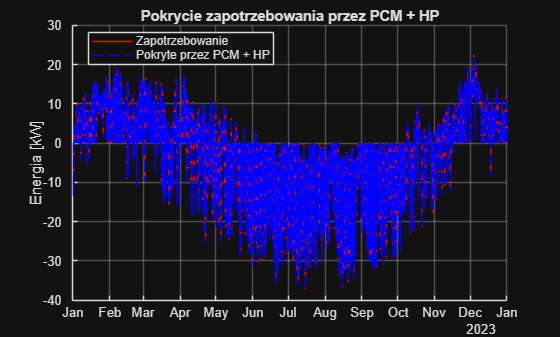






%% WYKRES: pokrycie zapotrzebowania przez PCM + HP - sprawdzamy czy jest przegrzanie/przechłodzenie
%Q_dem_net = T.Q_h_act - T.Q_c_act;
Q_HP_PCM = -Q_cool_PCM - Q_cool_HP + Q_heat_PCM + Q_heat_HP;  % suma dostrczanej energii przez PCM + HP
Q_c_HP_PCM = Q_cool_PCM + Q_cool_HP;                          % suma zapotrzebowania chłodniczego pokryta przez PCM + HP
Q_h_HP_PCM = Q_heat_PCM + Q_heat_HP;                          % suma zapotrzebowania gzrewczego pokryta przez PCM + HP
Q_err = Q_dem_net - Q_HP_PCM;
Q_err_max = Q_dem_net - T.Q_c_12 + T.Q_h_15 - Q_HP_PCM;      % maksymalne przegrzanie/przechłodzenie
Q_err_diff = Q_err_max - Q_err;




figure; hold on; grid on;
plot(T.time, Q_dem_net/1000, 'r');
plot(T.time, Q_HP_PCM/1000, 'b--');
title('Pokrycie zapotrzebowania przez PCM + HP');
legend('Zapotrzebowanie','Pokryte przez PCM + HP','Location','best');
ylabel('Energia [kW]');

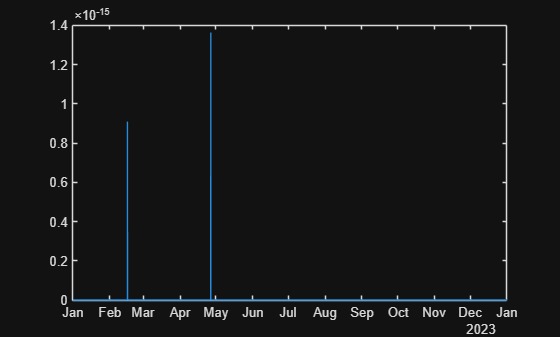


figure; grid on;
plot(T.time, Q_err/1000)

Q_err_sum = sum(abs(Q_err/1000))

Q_err_sum = 2.2737e-15



Q_heat_PCM_peak = max(Q_heat_PCM);
Q_cool_PCM_peak = max(Q_cool_PCM);

fprintf('Maksymalne chwilowe pokrycie grzania przez PCM: %.3f  kWh\n', Q_heat_PCM_peak/1000);

Maksymalne chwilowe pokrycie grzania przez PCM: 0.239  kWh


fprintf('Maksymalne chwilowe pokrycie chłodzenia przez PCM: %.3f  kWh\n', Q_cool_PCM_peak/1000);

Maksymalne chwilowe pokrycie chłodzenia przez PCM: 28.128  kWh


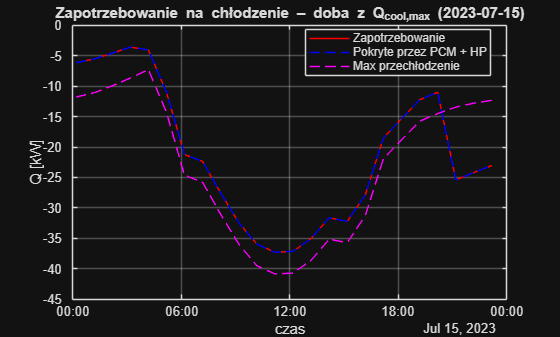



%najgorszy dzień dla chłodzenia
day_start = dateshift(t_cool_peak, 'start', 'day');
day_end   = day_start + days(1);
idx_day = (T.time >= day_start) & (T.time <= day_end);

%wykres 24h
figure; hold on; box on; grid on;
plot(T.time(idx_day), -T.Q_c_act(idx_day)/1000, 'r');
plot(T.time(idx_day), -Q_c_HP_PCM(idx_day)/1000, 'b--');
plot(T.time(idx_day), -T.Q_c_12(idx_day)/1000, 'm--');
yline(0);
xlabel('czas');
ylabel('Q [kW]');
title(sprintf('Zapotrzebowanie na chłodzenie – doba z Q_{cool,max} (%s)', datestr(day_start,'yyyy-mm-dd')));
legend('Zapotrzebowanie','Pokryte przez PCM + HP', 'Max przechłodzenie' ,'Location','best');
xlim([day_start day_end]);   


Qwym = sum(T.Q_c_act(idx_day))/1000;
fprintf('Suma zapotrzebowania chłodniczego w najgorszym dniu: %.4f kW\n', Qwym);

Suma zapotrzebowania chłodniczego w najgorszym dniu: 505.1477 kW


Q_cool_peak_day = sum(Q_c_HP_PCM(idx_day))/1000;
fprintf('Suma chłodzenia w najgorszym dniu: %.4f kW\n', Q_cool_peak_day);

Suma chłodzenia w najgorszym dniu: 505.1477 kW


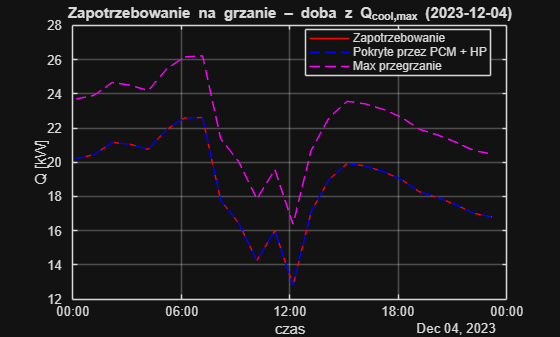





%najgorszy dzień dla grzania
day_start_heat = dateshift(t_heat_peak, 'start', 'day');
day_end_heat   = day_start_heat + days(1);
idx_day_heat = (T.time >= day_start_heat) & (T.time <= day_end_heat);

%wykres 24h
figure; hold on; box on; grid on;
plot(T.time(idx_day_heat), T.Q_h_act(idx_day_heat)/1000, 'r');
plot(T.time(idx_day_heat), Q_h_HP_PCM(idx_day_heat)/1000, 'b--');
plot(T.time(idx_day_heat), T.Q_h_15(idx_day_heat)/1000, 'm--');
xlabel('czas');
ylabel('Q [kW]');
title(sprintf('Zapotrzebowanie na grzanie – doba z Q_{cool,max} (%s)', datestr(day_start_heat,'yyyy-mm-dd')));
legend('Zapotrzebowanie','Pokryte przez PCM + HP','Max przegrzanie','Location','best');
xlim([day_start_heat day_end_heat]);   


Qwym_heat = sum(T.Q_h_act(idx_day_heat))/1000;
fprintf('Suma zapotrzebowania grzejnego w najgorszym dniu: %.4f kW\n', Qwym_heat);

Suma zapotrzebowania grzejnego w najgorszym dniu: 449.7976 kW


Q_heat_peak_day = sum(Q_h_HP_PCM(idx_day_heat))/1000;
fprintf('Suma grzania w najgorszym dniu: %.4f kW\n', Q_heat_peak_day);

Suma grzania w najgorszym dniu: 449.7976 kW


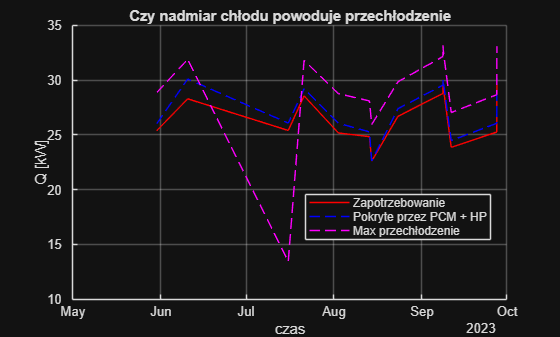




idx_over = Q_cool_over > 0;

Q_cool_tot = Q_c_HP_PCM + Q_cool_over;

figure; hold on; grid on;
plot(T.time(idx_over), Q_cool_dem(idx_over)/1000, 'r');
plot(T.time(idx_over), Q_cool_tot(idx_over)/1000, 'b--');
plot(T.time(idx_over), Q_c_12(idx_over)/1000, 'm--');
xlabel('czas');
ylabel('Q [kW]');
title('Czy nadmiar chłodu powoduje przechłodzenie')
legend('Zapotrzebowanie','Pokryte przez PCM + HP', 'Max przechłodzenie' ,'Location','best')

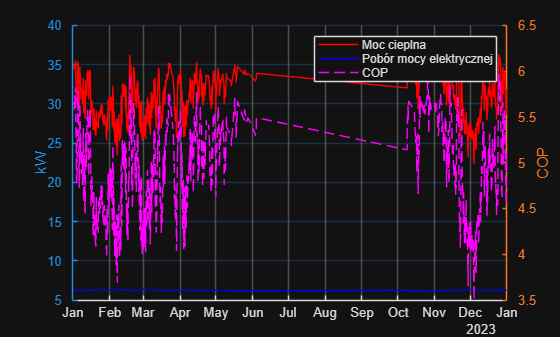




idx_HP_h_on = (Q_heat_HP > 0);

figure; hold on; grid on;
yyaxis left
h1=plot(T.time(idx_HP_h_on), Q_HP_h_nom(idx_HP_h_on)/1000, 'r-');
h2=plot(T.time(idx_HP_h_on), P_el_HP_heat(idx_HP_h_on)/1000, 'b-');
ylabel('kW');
yyaxis right
h3=plot(T.time(idx_HP_h_on), COP_HP_heat(idx_HP_h_on), 'm--');
ylabel('COP');
legend([h1 h2 h3],'Moc cieplna', 'Pobór mocy elektrycznej', 'COP')

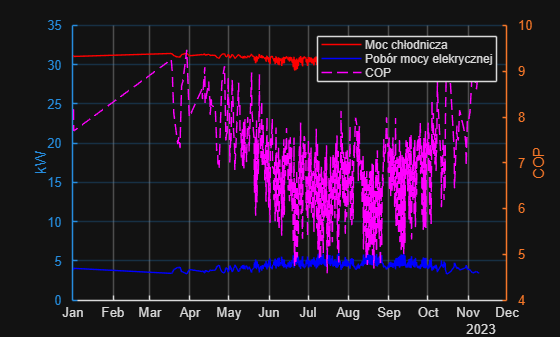



idx_HP_c_on = (Q_cool_HP > 0);

figure; hold on; grid on;
yyaxis left
h4=plot(T.time(idx_HP_c_on), Q_HP_c_nom(idx_HP_c_on)/1000, 'r-');
h5=plot(T.time(idx_HP_c_on), P_el_HP_cool(idx_HP_c_on)/1000, 'b-');
ylabel('kW');
yyaxis right
h6=plot(T.time(idx_HP_c_on), COP_HP_cool(idx_HP_c_on), 'm--');
ylabel('COP');
legend([h4 h5 h6],'Moc chłodnicza', 'Pobór mocy elekrycznej', 'COP')




P_el_HP_cool_sum = sum(P_el_HP_cool(idx_HP_c_on));
P_el_HP_heat_sum = sum(P_el_HP_heat(idx_HP_h_on));
P_el_HP_sum = P_el_HP_heat_sum + P_el_HP_cool_sum;


fprintf('Suma energii elektrycznej na prace pompy podczas grzania: %.2f kWh\n', P_el_HP_heat_sum/1000);

Suma energii elektrycznej na prace pompy podczas grzania: 19278.99 kWh


fprintf('Suma energii elektrycznej na prace pompy podczas chłodzenia: %.2f kWh\n', P_el_HP_cool_sum/1000);

Suma energii elektrycznej na prace pompy podczas chłodzenia: 6726.48 kWh


fprintf('Suna energii elektrycznej na prace pompy: %.2f kWh\n', P_el_HP_sum/1000);

Suna energii elektrycznej na prace pompy: 26005.47 kWh


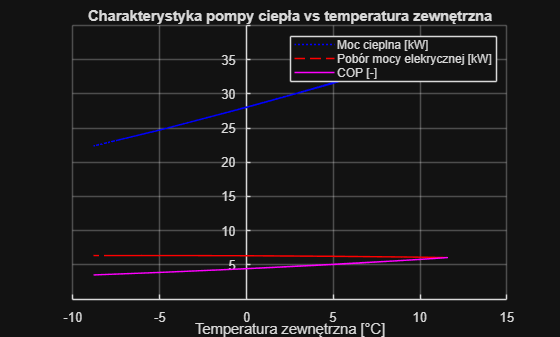





figure; hold on; grid on;
plot(T.temp_zew(idx_HP_h_on), Q_HP_h_nom(idx_HP_h_on)/1000, 'b:');
plot(T.temp_zew(idx_HP_h_on), P_el_HP_heat(idx_HP_h_on)/1000, 'r--');
plot(T.temp_zew(idx_HP_h_on), COP_HP_heat(idx_HP_h_on), 'm-');
legend('Moc cieplna [kW]', 'Pobór mocy elekrycznej [kW]', 'COP [-]')
title('Charakterystyka pompy ciepła vs temperatura zewnętrzna')
xlabel('Temperatura zewnętrzna [°C]')
ax = gca;
ax.XAxisLocation = 'origin'; 
ax.YAxisLocation = 'origin';  

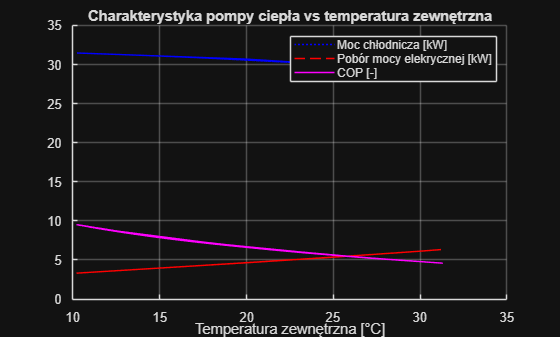



figure; hold on; grid on;
plot(T.temp_zew(idx_HP_c_on), Q_HP_c_nom(idx_HP_c_on)/1000, 'b:');
plot(T.temp_zew(idx_HP_c_on), P_el_HP_cool(idx_HP_c_on)/1000, 'r--');
plot(T.temp_zew(idx_HP_c_on), COP_HP_cool(idx_HP_c_on), 'm-');
legend('Moc chłodnicza [kW]', 'Pobór mocy elekrycznej [kW]', 'COP [-]')
title('Charakterystyka pompy ciepła vs temperatura zewnętrzna')
xlabel('Temperatura zewnętrzna [°C]')